EEE Subjects 1,2,3 Total Effect Readout:

cd('C:\Users\bgrau\GitHub\ieeg_affect\EEE\subjects\sub-03\ses-01')
% clear all
load('stim_table_full.mat')
stim_table = renamevars(stim_table, ["exp_rating", "val_rating", "trial_number"], ["exp_rate", "img_rate", "trial"]);

stim_table = movevars(stim_table, 'img_rate', 'After', 'cue_observed_mean');
stim_table = stim_table(:, [1:4 6:9 11 12 14 15 31 33]);

cs = find(contains(stim_table.Properties.VariableNames, 'mean'));
stim_table{:,cs} = (stim_table{:,cs} - 1)/6*100;

cs = find(contains(stim_table.Properties.VariableNames, 'SD'));
stim_table{:,cs} = (stim_table{:,cs})/6*100;

cs = find(contains(stim_table.Properties.VariableNames, 'std'));
stim_table{:,cs} = (stim_table{:,cs})/6*100;

cs = find(contains(stim_table.Properties.VariableNames, 'difference'));
stim_table{:,cs} = (stim_table{:,cs})/6*100;

cs = find(contains(stim_table.Properties.VariableNames, 'deviation'));
stim_table{:,cs} = (stim_table{:,cs})/6*100;

cs = find(contains(stim_table.Properties.VariableNames, 'rate'));
stim_table{:,cs} = (stim_table{:,cs} - 1)/6*100;


stim_table = sortrows(stim_table,"Pair","ascend");

%% ALL SUBJECTS %%%
% clearvars -except subtable
% stim_table = sortrows(subtable,"Pair","ascend");

cuehl = stim_table.highcue_indx;
cuemean = stim_table.cue_observed_mean;
pair = stim_table.Pair;
rating = stim_table.img_rate;
stimmean = stim_table.Valence_mean;

wh_high = cuehl > 0;
wh_low = cuehl < 0;

hi_table = stim_table(wh_high, :);
lo_table = stim_table(wh_low, :);


pair_table = table;
pair_table.pair_number = hi_table.Pair;
pair_table.hi_cue = hi_table.img_rate;
pair_table.lo_cue = lo_table.img_rate;
pair_table.rating_mean = (hi_table.img_rate + lo_table.img_rate)/2;
pair_table.cue_mean = (hi_table.cue_observed_mean + lo_table.cue_observed_mean)/2;
pair_table.cue_sd = (hi_table.cue_observed_std + lo_table.cue_observed_std)/2;
pair_table.stim_mean = (hi_table.Valence_mean + lo_table.Valence_mean)/2;
pair_table.stim_sd = (hi_table.Valence_SD + lo_table.Valence_SD)/2;
pair_table.rating_diff = hi_table.img_rate - lo_table. img_rate;
pair_table.stim_diff = (hi_table.Valence_mean - lo_table.Valence_mean);
pair_table.norm_hi = pair_table.hi_cue - pair_table.rating_mean;
pair_table.norm_lo = pair_table.lo_cue - pair_table.rating_mean;
d = pair_table.rating_diff;

% Two-tailed
[hyp, pval, ci, stat] = ttest(pair_table.hi_cue, pair_table.lo_cue, 'Tail', 'right');
fprintf('High vs. low cue effect: M = %3.2f, SE = %3.2f, t(%3.0f) = %3.2f, p = %3.6f\n', mean(d), ste(d), stat.df(1), stat.tstat(1), pval(1));

High vs. low cue effect: M = 6.56, SE = 3.68, t( 31) = 1.78, p = 0.042206







% sub1mean = mean(pair_table.rating_diff)
% sub1ci = ci
% sub1SE = ste(d)
% sub1pairtable = pair_table;

% sub2mean = mean(pair_table.rating_diff)
% sub2ci = ci
% sub2SE = ste(d)
% sub2pairtable = pair_table;

sub3mean = mean(pair_table.rating_diff)

sub3mean = 6.5592

sub3ci = ci

sub3ci =     0.3212
       Inf


sub3SE = ste(d)

sub3SE = 3.6792

sub3pairtable = pair_table;



figure; hold on;
y = [mean(sub1pairtable.lo_cue) mean(sub1pairtable.rating_diff); mean(sub2pairtable.lo_cue)  ...
     mean(sub2pairtable.rating_diff); mean(sub3pairtable.lo_cue) mean(sub3pairtable.rating_diff)]

y =    47.7397    6.6569
   55.1188    2.8625
   54.2440    6.5592


% bar(y, 'stacked')
errlow = [mean(sub1pairtable.rating_diff)-sub1SE, mean(sub2pairtable.rating_diff)-sub2SE, mean(sub3pairtable.rating_diff)-sub3SE]

errlow =     4.2622    0.2391    2.8801


errhigh = [mean(sub1pairtable.rating_diff)+sub1SE, mean(sub2pairtable.rating_diff)+sub2SE, mean(sub3pairtable.rating_diff)+sub3SE]

errhigh =     9.0516    5.4860   10.2384


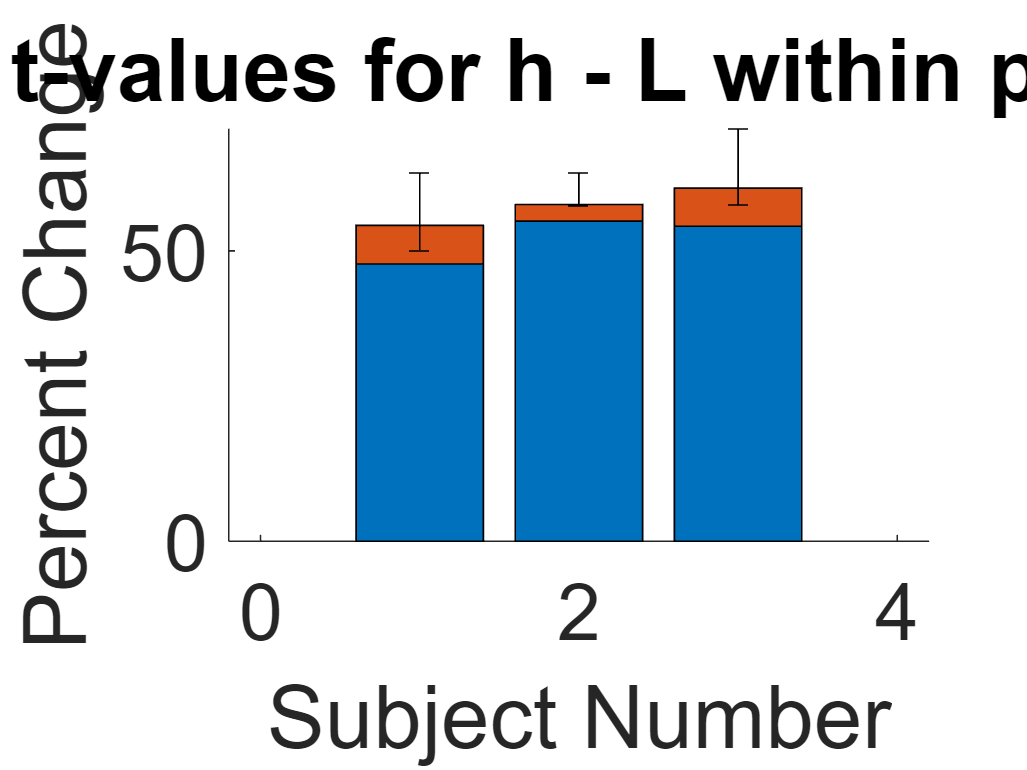


er = errorbar([1:3],[mean(sub1pairtable.hi_cue),mean(sub2pairtable.hi_cue), mean(sub3pairtable.hi_cue)],errlow,errhigh);    
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 

set(gca, 'FontSize', 24)
scn_export_papersetup(400);
ylabel('Percent Change');
xlabel('Subject Number');
title('t-values for h - L within pair')

% set(gca, 'YTick', 1:5:28, 'YTickLabel', imgview_freq.freq);

Cue Effect (ordered by pair number)

cuecolors = {[1 0 0] [0 0 1]};


y = [pair_table.hi_cue pair_table.lo_cue];  % ratings, [high low]
% y = [pair_table.norm_hi pair_table.norm_lo];
x = [pair_table.pair_number pair_table.pair_number];  % pairs, [high low]


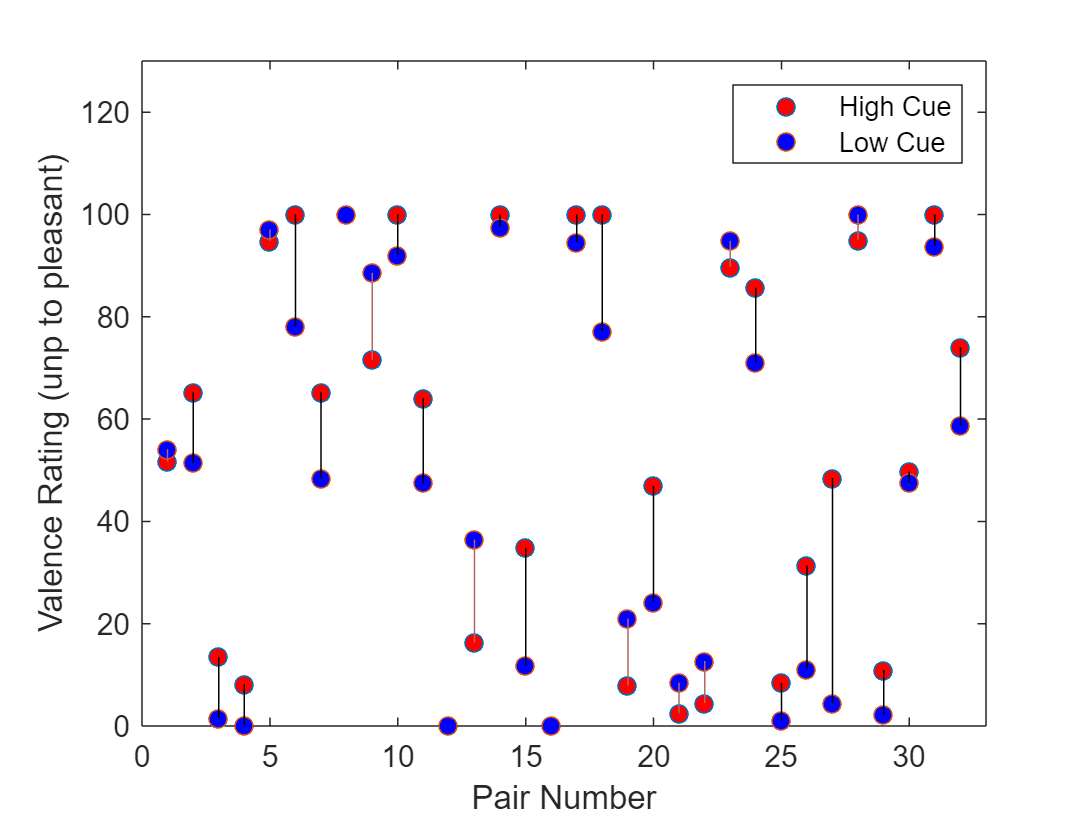


highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;

lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); 

% meandots = plot(pair_table.cue_mean, 'o', 'MarkerFaceColor', 'g');


d = -(diff(y')'); % h - l difference scores for matched pairs

wh_hvsl = d > 0;
line = plot(x(wh_hvsl, :)', y(wh_hvsl, :)', 'k-');
line = plot(x(~wh_hvsl, :)', y(~wh_hvsl, :)', '-', 'Color', [.7 .4 .4]);

xlabel('Pair Number');
ylabel('Valence Rating (unp to pleasant)')


% hold off;
axis([0 33 0 130])
legend([highdots lowdots], {'High Cue', 'Low Cue'})
hold off;

drawnow()

% fig2plotly(gcf)

ans =   1×12 Violin array with properties:

    ScatterPlot
    ScatterPlot2
    ViolinPlot
    ViolinPlot2
    BoxPlot
    WhiskerPlot
    MedianPlot
    NotchPlots
    MeanPlot
    HistogramPlot
    ViolinPlotQ
    ViolinColor
    ViolinAlpha
    MarkerSize
    MedianMarkerSize
    LineWidth
    EdgeColor
    BoxColor
    BoxWidth
    MedianColor
    ShowData
    ShowNotches
    ShowMean
    ShowBox
    ShowMedian
    ShowWhiskers
    HalfViolin


% Violin Plots
violinplot(pair_table)

drawnow()

I think that there's something interesting happening when individuals have strong pre-existing preferences for an image. I'll try to quantify that by looking at ratings that are more than 2 SD away from the normative mean. 

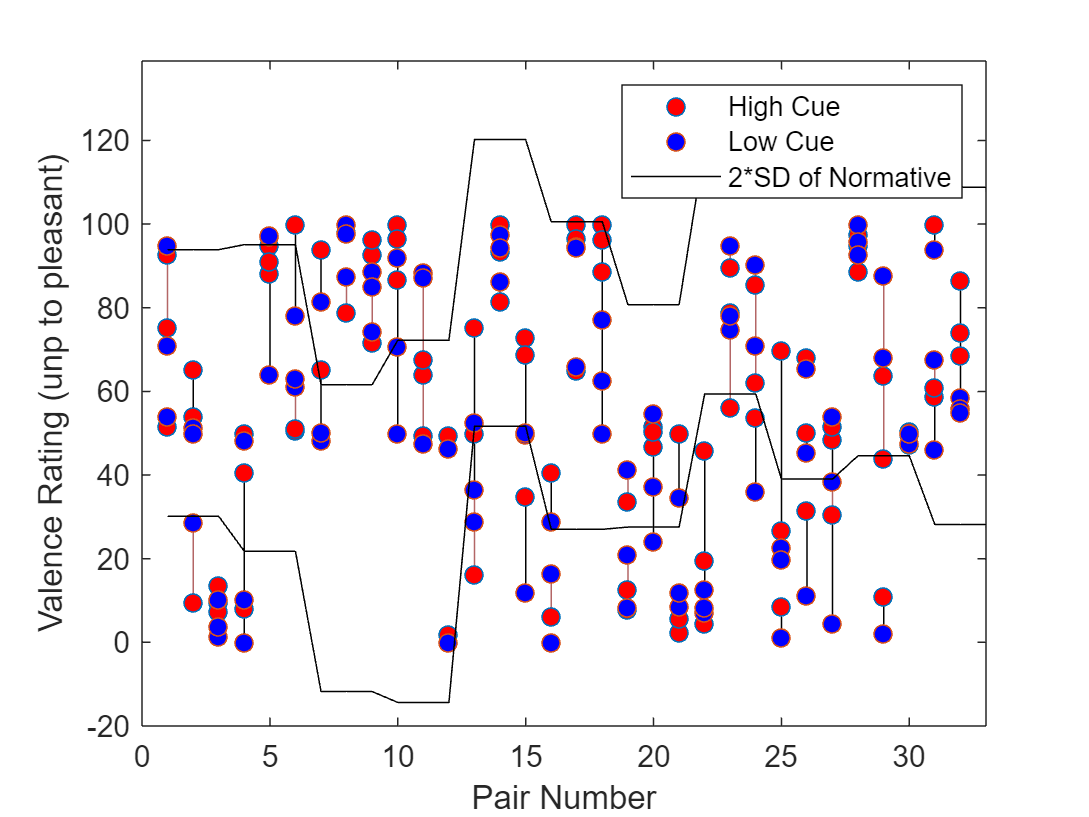

hi_sd = pair_table.stim_mean + (2*pair_table.stim_sd);
lo_sd = pair_table.stim_mean - (2*pair_table.stim_sd);
hold on;
highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;

lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); 

% meandots = plot(pair_table.cue_mean, 'o', 'MarkerFaceColor', 'g');

sd_up = plot(hi_sd, 'k-');
sd_down = plot(lo_sd, 'k-');

xlabel('Pair Number');
ylabel('Valence Rating (unp to pleasant)')
hold off;
axis([0 33 -20 139])
legend([highdots lowdots sd_up], {'High Cue', 'Low Cue', '2*SD of Normative'})

Cue Effect (ordered from largest to smallest)

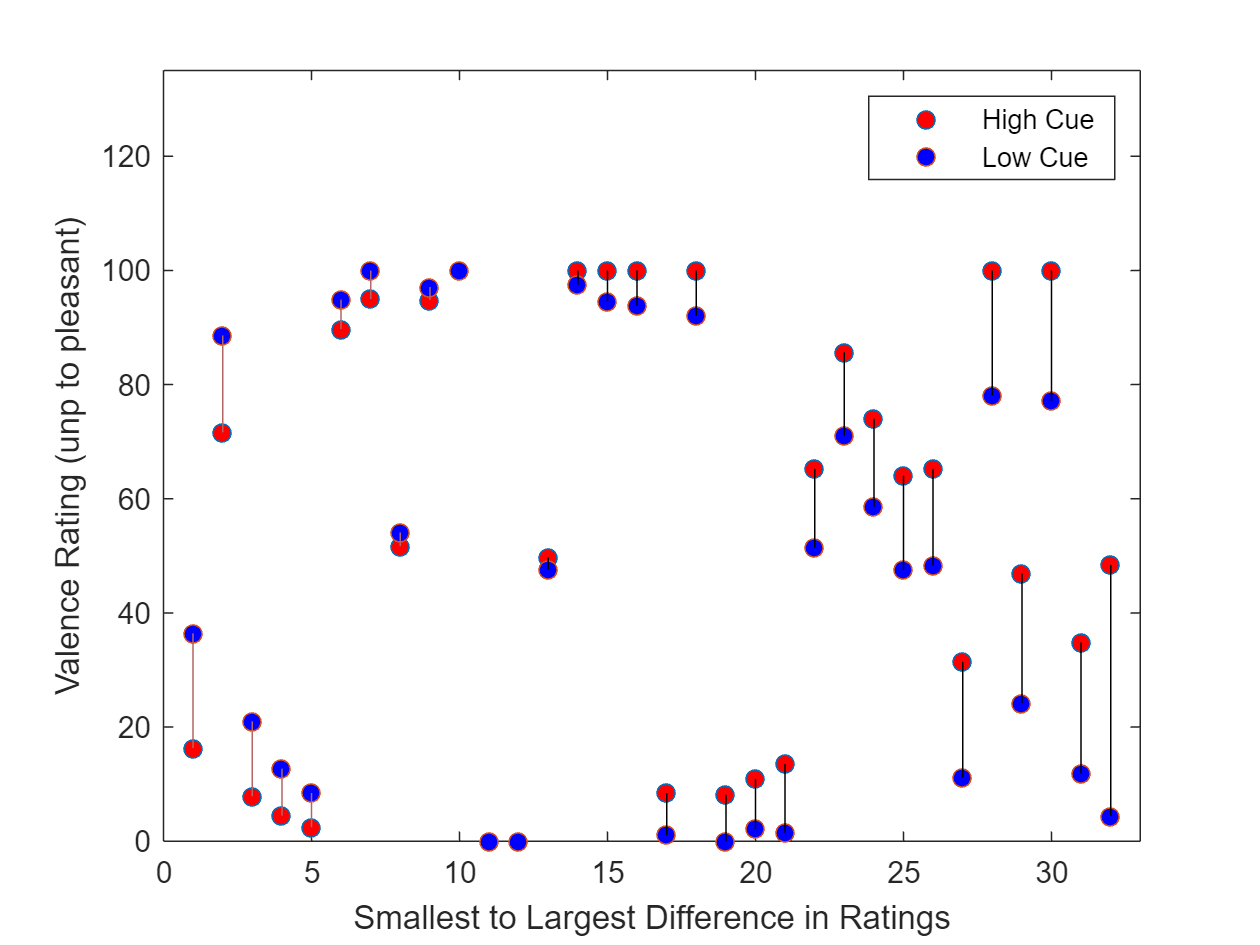

pair_table = sortrows(pair_table,"rating_diff","ascend");

pairs = [1:32]';

y = [pair_table.hi_val pair_table.lo_val];  % ratings, [high low]
x = [pairs pairs];  % pairs, [high low]


highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;

lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); 

d = -(diff(y')'); % h - l difference scores for matched pairs

wh_hvsl = d > 0;
line = plot(x(wh_hvsl, :)', y(wh_hvsl, :)', 'k-');
line = plot(x(~wh_hvsl, :)', y(~wh_hvsl, :)', '-', 'Color', [.7 .4 .4]);


xlabel('Smallest to Largest Difference in Ratings');
ylabel('Valence Rating (unp to pleasant)')
hold off;

axis([0 33 0 135])
legend([highdots lowdots], {'High Cue', 'Low Cue'})

Control of Cue Effect 

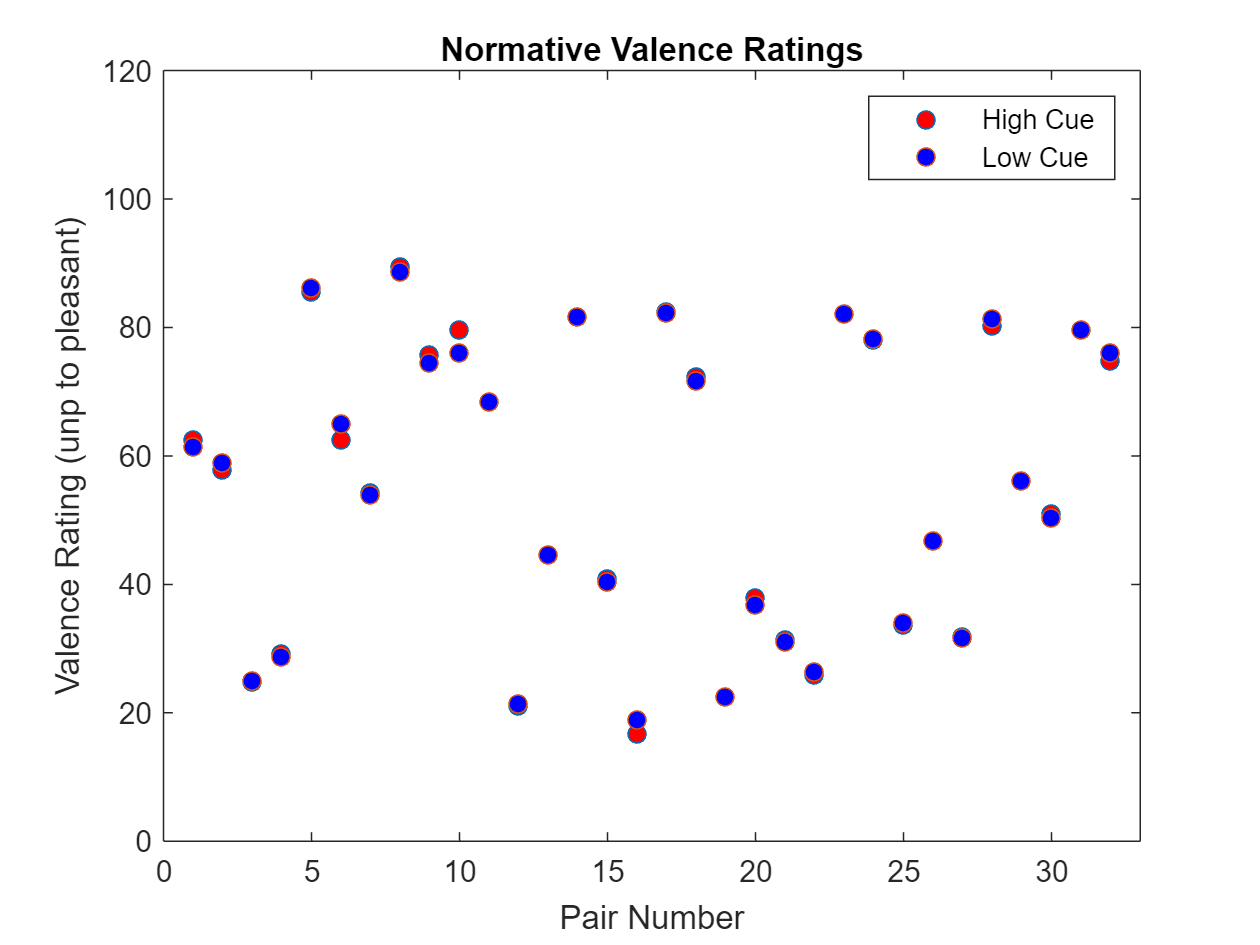



y = [hi_table.Valence_mean lo_table.Valence_mean];  % ratings, [high low]
x = [hi_table.Pair lo_table.Pair];  % pairs, [high low]

highdots = plot(x(:, 1), y(:, 1), 'o', 'MarkerFaceColor', cuecolors{1}); hold on;

lowdots = plot(x(:, 2), y(:, 2), 'o', 'MarkerFaceColor', cuecolors{2}); hold off;

xlabel('Pair Number');
ylabel('Valence Rating (unp to pleasant)')
title('Normative Valence Ratings')
hold off;
axis([0 33 0 120])
legend([highdots lowdots], {'High Cue', 'Low Cue'})

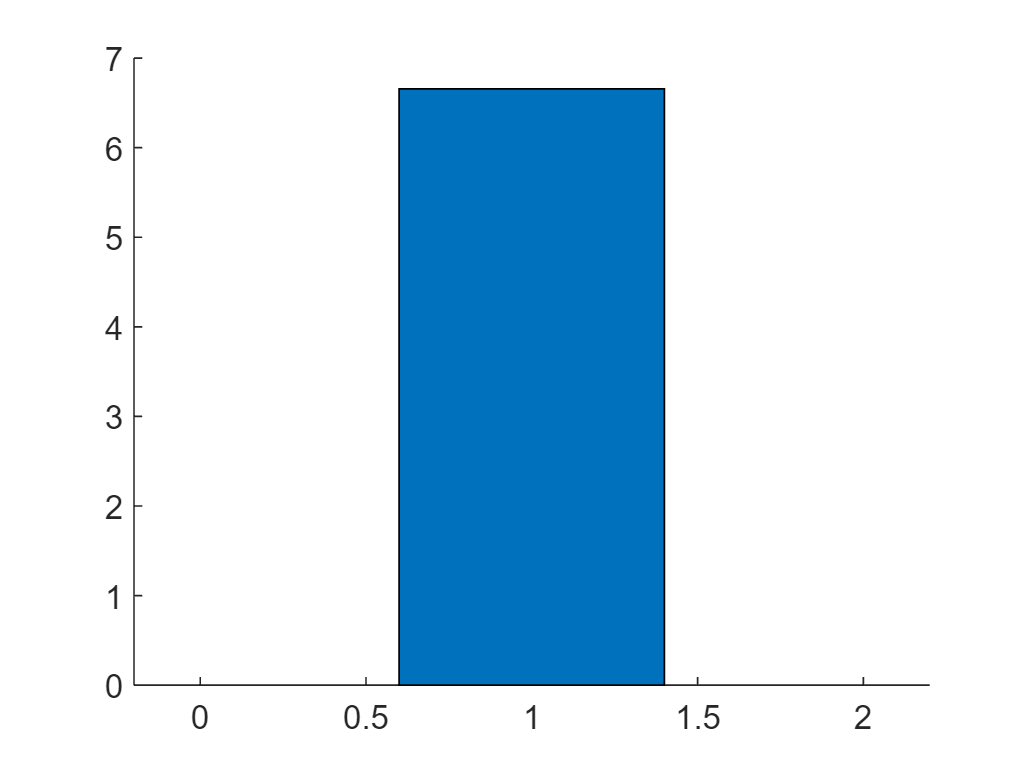

Averge Effect: 

% % Extract and compute normative H-L cue picture rating differences
normative_diff = pair_table.stim_diff;
% 
% Perform the regression model
X = [ones(size(normative_diff, 1), 1), normative_diff];
y = pair_table.rating_diff;
coeffs = regress(y, X);

% Extract the intercept term (effect of interest)
intercept = coeffs(1);

% Display the results
fprintf('Intercept (patient average H-L cue effect): %.4f\n', intercept);

Intercept (patient average H-L cue effect): 6.4244
